experiment = loadExp

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5105×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [1×67777279 double]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
                Whisking: [1×1 struct]
               timeStamp: []
            analysisType: {'sound events'  'continuous whisking'  'discrete whisking'  'no whisking periods'}
            time2discard: []


expLength = length(experiment.sound.full)

expLength = 67777280

% unitTrain = nonzeros(experiment.Units.good.times(2,1:3000));
% expLength = unitTrain(end)

%  s3 = getSDF(unitTrain,expLength);

expLength = 14671250

sound = experiment.sound.full;

[b,a] = butter(3,2000/15000,"high")
sound = filtfilt(b,a,double(sound))
sound = envelope(sound)

b =     0.6557   -1.9671    1.9671   -0.6557


a =     1.0000   -2.1677    1.6480   -0.4299


orderedVec = [experiment.conditionVector.aluminum';experiment.conditionVector.muted';experiment.conditionVector.non';experiment.conditionVector.noWhisking']

sound = 	1.0e+03 *

   -0.0008    0.0063    0.0021    0.0302   -0.0379    0.0198    0.0025    0.0179    0.0156   -0.0030   -0.0354   -0.0440    0.0297    0.0168   -0.0016   -0.0056    0.0041    0.0035   -0.0034   -0.0056    0.0417   -0.0135   -0.0275    0.0188   -0.0297   -0.0156    0.0165   -0.0168    0.0290    0.0033    0.0352    0.0075   -0.0331   -0.0312    0.0336   -0.0022    0.0080   -0.0122   -0.0379    0.0497   -0.0171   -0.0150   -0.0206    0.0136    0.0244    0.0000    0.0278    0.0058   -0.0221   -0.0182


objClassRe = [resampObjCon(experiment.conditionVector.aluminum,1);resampObjCon(experiment.conditionVector.muted,2);resampObjCon(experiment.conditionVector.non,3);resampObjCon(experiment.conditionVector.noWhisking,0)];

sound = 	1.0e+04 *

    0.0004    0.0017    0.0015    0.0043    0.0039    0.0030    0.0016    0.0020    0.0035    0.0024    0.0049    0.0059    0.0042    0.0021    0.0012    0.0006    0.0004    0.0004    0.0010    0.0022    0.0042    0.0048    0.0031    0.0019    0.0038    0.0041    0.0017    0.0024    0.0032    0.0004    0.0035    0.0047    0.0040    0.0041    0.0039    0.0026    0.0012    0.0042    0.0056    0.0050    0.0038    0.0017    0.0023    0.0039    0.0027    0.0005    0.0028    0.0032    0.0031    0.0020


sound = sound(orderedVec)

orderedVec = 57461850×1 int64 column vector
   10437128
   10437129
   10437130
   10437131
   10437132
   10437133
   10437134
   10437135
   10437136
   10437137


sound =resample(sound,1000,30000)

for good = 1:length(experiment.Units.good.id)

sound = 	1.0e+03 *

    0.0377    0.0403    0.0146    0.0194    0.0316    0.0224    0.0231    0.0515    0.0640    0.0501    0.0351    0.0420    0.0370    0.0142    0.0255    0.0454    0.0570    0.0319    0.0338    0.0859    0.0693    0.0062    0.0575    0.0524    0.0484    0.0684    0.0565    0.0320    0.0043    0.0466    0.0740    0.0565    0.0289    0.0726    0.0756    0.0160    0.0616    0.0926    0.0580    0.0445    0.0702    0.0539    0.0391    0.0375    0.0094    0.0380    0.0634    0.0487    0.0026    0.0422


    unitTrain = nonzeros(experiment.Units.good.times(good,:));
    s3 = getSDF(unitTrain,orderedVec);

sound =    19.7657   49.3566   46.7511   41.2946   36.0525   39.0416   34.9920   40.0358   27.2183   38.6788   68.1403   41.3751   35.6016   35.0780   31.3855   26.8654   32.0160   33.2012   32.9431   36.3661   32.5480   35.5233   32.5341   28.9823   35.4829   34.7918   36.8991   29.9008   21.3914   35.5932   30.7232   26.4014   43.3131   27.0195   29.8013   31.2471   40.0833   35.5197   42.4055   57.4029   42.9138   38.5326   46.4737   35.1586   41.5798   39.2722   33.0561   33.7729   31.5304   27.6339


    allSDF(good,:) = s3; 
end

allSDF =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

for mua = 1:length(experiment.Units.mua.id)
    unitTrain = nonzeros(experiment.Units.mua.times(mua,:));
    s3 = getSDF(unitTrain,expLength);
    allSDF(good+mua,:) = s3;
end




[c,lags] = xcorr(allSDF(5,:),sound,'normalized');

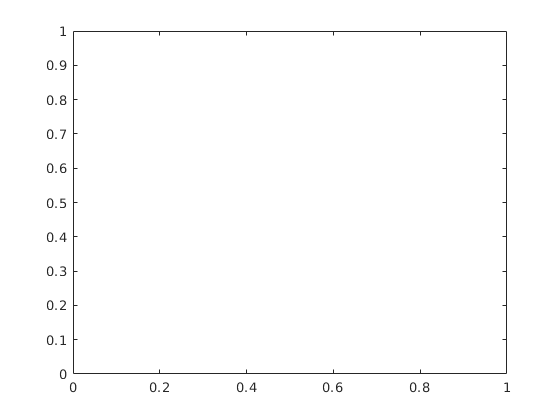

plot(lags,c)


[c,lags] = xcorr(allSDF(2,(objClassRe==1)),sound(objClassRe==1),'normalized');

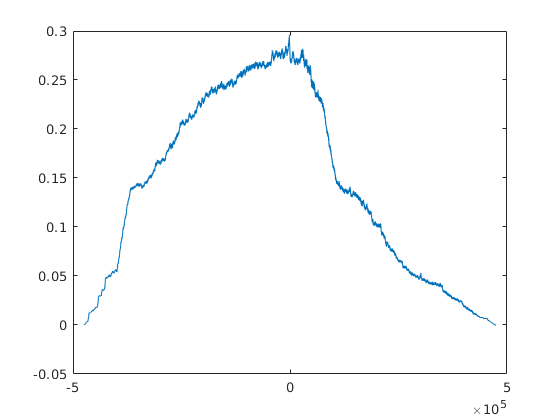

plot(lags,c)

function spikeVec = getSDF(unitTrain,timeVec)
unitFiring = ismember(timeVec,unitTrain);
sigma = .015;
edges = [-3*sigma:1/30000:3*sigma];
kernel = normpdf(edges,0,sigma);
kernel = kernel*1/30000;
s = conv(unitFiring,kernel);
center = ceil(length(edges)/2);
s = s(center:length(timeVec)+center-1);
spikeVec = resample(s,1000,30000);
end

function objCond = resampObjCon(conditionVector,objClass)
reCond = resample(double(conditionVector),1000,30000);
objCond = ones(length(reCond),1)*objClass;

end